# Specify Colormap Colors for Surface Plot

Specify the colors for a surface plot by including a fourth matrix input, `C`. The surface plot uses `Z` for height and `C` for color. Specify the colors using a *colormap*, which uses single numbers to stand for colors on a spectrum. When you use a colormap, `C` is the same size as `Z`. Add a color bar to the graph to show how the data values in `C` correspond to the colors in the colormap.

csv = readtable('variations.csv')

csv = 280×8 table
    depth2    depth3    polywidth2    polywidth3    resonance2    resonance3    q_factor2    q_factor3
    ______    ______    __________    __________    __________    __________    _________    _________

      2         3          0.1           0.1          298.68        224.12       7.6987       7.7128  
      2         3          0.2           0.2          424.48        317.91       10.941        10.94  
      2         3          0.3           0.3          522.48        390.28       13.468       13.431  
      2         3          0.4           0.4          606.21        452.03       15.626       15.556  
      2         3          0.5           0.5          680.87        506.94        17.55    

depth2 = csv.depth2;
depth3 = csv.depth3;

polywidth2 = csv.polywidth2;
polywidth3 = csv.polywidth3;

resonance2 = csv.resonance2;
resonance3 = csv.resonance3;

q_factor2 = csv.q_factor2;
q_factor3 = csv.q_factor3;

% preallocate space to speed up calculations
depth = zeros(length(depth2)*2, 1)

depth =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


polywidth = zeros(length(depth2)*2, 1);
resonance = zeros(length(depth2)*2, 1);
% keep track of the index in the depth, polywidth, and resonance arrays
index = 1

index = 1


% alternate the data to be depth 2 values, depth 3 values, depth 2 values,
% ... depth 3 values
% for counter = 1 : length(depth2)
%     % first (and every odd) value should be depth 2
%     if(mod(counter, 2) == 1)
%         depth(counter, :) = depth2(index);
%         polywidth(counter, :) = polywidth2(index);
%         resonance(counter, :) = resonance2(index);
%     else
%         depth(counter, :) = depth3(index);
%         polywidth(counter, :) = polywidth3(index);
%         resonance(counter, :) = resonance3(index);
%         % after adding depth 3 values, increment the index
%         index = index + 1;
%     end
% end


range = 10;
depth = zeros(range, 1);
polywidth = zeros(range, 1);
resonance = zeros(range, 1);
q_factor = zeros(range, 1);

for counter = 1 : range/2
    % first (and every odd) value should be depth 2
    
        depth(index, :) = depth2(index);
        polywidth(index, :) = polywidth2(index);
        resonance(index, :) = resonance2(index);
        q_factor(index, :) = q_factor2(index);
        index = index + 1;
end


for counter = 1 : range/2
        depth(index, :) = depth3(counter);
        polywidth(index, :) = polywidth3(counter);
        resonance(index, :) = resonance3(counter);
        q_factor(index, :) = q_factor3(index);
        
        index = index + 1;
end

% disp(depth)
% disp(polywidth)
% disp(resonance)
% 
% 
% 
% 
% linSpace1 = linspace(0, 1, 255)'
% linSpace2 = linspace(0, 1, 255)'
% zeros(255, 1)
% 
% yellowMap = [linSpace1, linSpace2, zeros(255, 1)]
% colorYellow = colormap(yellowMap);



Z = [depth(1:range, :), polywidth(1:range, :), q_factor(1:range, :)]

Z =     2.0000    0.1000    7.6987
    2.0000    0.2000   10.9413
    2.0000    0.3000   13.4675
    2.0000    0.4000   15.6257
    2.0000    0.5000   17.5501
    3.0000    0.1000   19.1561
    3.0000    0.2000   20.7410
    3.0000    0.3000   22.2427
    3.0000    0.4000   23.6497
    3.0000    0.5000   24.9905


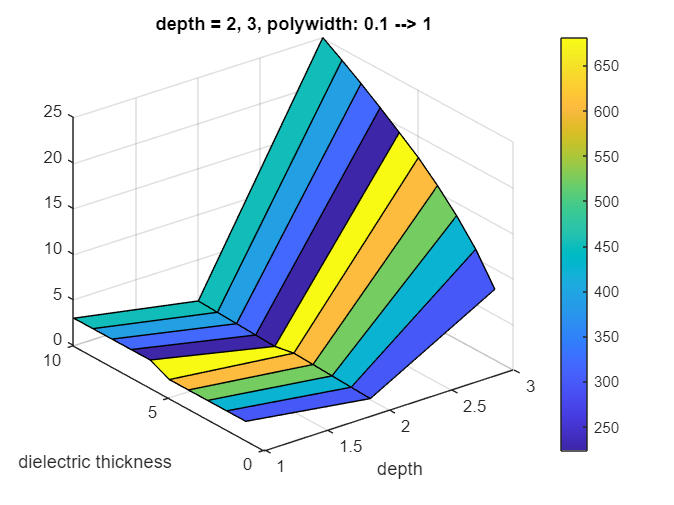


Cmesh = [resonance(1:range, :), resonance(1:range, :), resonance(1:range, :)];

surf(Z, Cmesh)
colorbar
title('depth = 2, 3, polywidth: 0.1 --> 1')
xlabel('depth')
ylabel('dielectric thickness')





        X = depth(1:range, :);
Y = polywidth(1:range, :);
Z = q_factor(1:range, :);
colorGrid = resonance(1:range, :);

xv = linspace(min(depth), max(depth), range);
yv = linspace(min(polywidth), max(polywidth), range);
[Xmesh, Ymesh] = meshgrid(xv, yv);
zv = linspace(min(q_factor), max(q_factor), range);
Zmesh = meshgrid(zv);
cv = linspace(min(resonance), max(resonance), range);
Cmesh = meshgrid(cv);



Z = [depth(1:range, :), polywidth(1:range, :), q_factor(1:range, :)]
surf(Z)

% [X, Y] = meshgrid(depth(1:range, :), polywidth(1:range, :))
% disp(X)
% disp(Y)
% Z = meshgrid(q_factor(1:range, :))
% colorGrid = meshgrid(resonance(1:range, :))

% disp(Z)
% disp(colorGrid)

% surf(X, Y, Z, colorGrid)
% plot3(X, Y, Z)
% stem3(X, Y, Z)


s = surf(Xmesh, Ymesh, Zmesh, Cmesh);
disp(s)
title('depth = 2, polywidth: 0.1 --> 1')
xlabel('depth')
ylabel('polywidth')
colorbar


Z = [depth, polywidth, q_factor]

% mesh(Z)
mesh(Z)


% [X, Y, Z] = meshgrid(depth, polywidth, q_factor)


size_vector= ones(560, 1) 





Z = [depth(1:30, :), polywidth(1:30, :), q_factor(1:30, :)]
width = 100
b = bar3(Z)
% 
% colormap(resonance)
% 
% for i = 1 : length(b)
%     b(i).FaceAlpha = '1.0';
% end
% colorbar

s = scatter3(depth, polywidth, q_factor, size_vector, resonance, 'filled')
s.SizeData = 10;
colorbar




% _----------------------------------------------------------------------------------

% tbl = readtable('var.csv')
% scatter3(tbl, 'depth', 'polywidth', 'q_factor', 'filled', 'ColorVariable', 'resonance');
% 
% colorbar


% [X,Y] = meshgrid(3:4, 0:0.1:2);
% 
% disp("X:")
% disp(X)
% disp("Y:")
% disp(Y)
% Z = [1 0; 2 0; 3 0; 4 0; 5 0; 6 0; 7 0; 8 0; 9 0; 1 0; 2 0; 3 0; 4 0; 5 0; 6 0; 7 0; 8 0; 9 0; 1 0; 2 0; 3 0];
% disp(Z)
% C = Z;
% disp(C)
% surf(depth,polywidth,q_factor,resonance)

*Copyright 2012 The MathWorks, Inc.*